clearvars;
load lombardgrid_paired/alignments_fixed.mat
load lombardgrid_paired/corpusCleaned.mat

savefolder = 'seg_STfilter';
savefile = 'result';

% s10_p_swar4p

% mikke = contains(corpusCleaned.SPKR,'s10') & contains(corpusCleaned.UTTERANCE,'swar4p');
% 
% corpusCleaned = corpusCleaned(mikke,:)
% 
measure_method = 6;

tic
segmentModification(corpusCleaned, alignments, savefolder, savefile, measure_method);

   100

   200

   300

   400

   500

   600

   700

   800

   900

        1000

        1100

        1200

        1300

        1400

        1500

        1600

        1700

        1800

        1900

        2000

        2100

        2200

        2300

        2400

        2500



toc

Elapsed time is 388.641134 seconds.


clearvars;
load lombardgrid_paired/alignments_fixed.mat
load lombardgrid_paired/corpusCleaned.mat

savefolder = 'seg_LPCfilter';
savefile = 'result';

measure_method = 6;

tic
segmentModification(corpusCleaned, alignments, savefolder, savefile, measure_method, 'lpc');

   100

   200

   300

   400

   500

   600

   700

   800

   900

        1000

        1100

        1200

        1300

        1400

        1500

        1600

        1700

        1800

        1900

        2000

        2100

        2200

        2300

        2400

        2500



toc

Elapsed time is 270.384281 seconds.


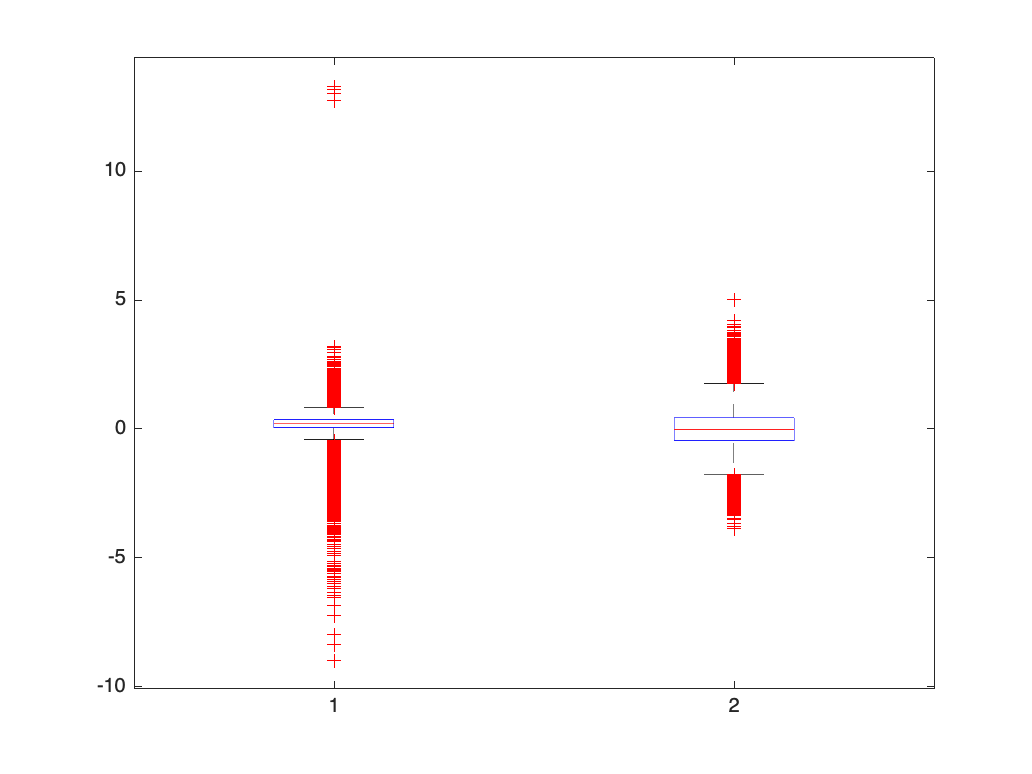

clearvars;
load seg_STfilter/result.mat
abserr_seg_ST = result.abserr_seg;

load seg_LPCfilter/result.mat

abserr_seg_LPC = result.abserr_seg;

boxplot([abserr_seg_ST,abserr_seg_LPC])


fprintf('mean:%.5f sigma:%.5f',mean(abserr_seg_ST),std(abserr_seg_ST))

mean:0.13324 sigma:0.62156


fprintf('mean:%.5f sigma:%.5f',mean(abserr_seg_LPC),std(abserr_seg_LPC))

mean:0.00189 sigma:0.77506